### GENERACIÓN DE SÍMBOLOS Y NORMALIZACIÓN

Se generan las señales que representan cada símbolo.

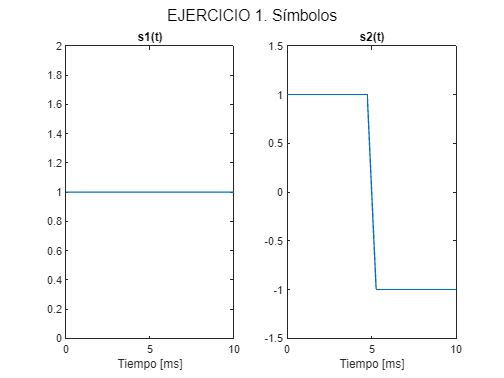

% Definición de parámetros para la generación de señales
T = 1e-2; % Tiempo de símbolo [s/simbolo]
Ts = T/20; % Periodo de símbolo [s/muestras]
fs = 1/Ts; % Frecuencia de símbolo [muetras/s]
N= fs*T;   % Muestras por símbolo [muestras/simbolo]

% Generación de símbolos
s1 = ones(1,N);
s2 = [ones(1,N/2), -1.*ones(1,N/2)];

% Generación eje de tiempos
t = linspace(0,N*Ts*1e3,N);

% Representación de señales
figure;
sgtitle("EJERCICIO 1. Símbolos")
subplot(1,2,1);
plot(t,s1);
xlim([0,T*1e3]);
title("s1(t)");
xlabel("Tiempo [ms]");

subplot(1,2,2);
plot(t,s2);
ylim([-1.5,1.5]);
xlim([0,T*1e3]);
title("s2(t)");
xlabel("Tiempo [ms]");

Una vez obtenida la expresión de los símbolos, es necesario plantearse si estos forman una base ortonormal. Se trabajará en el dominio muestral de la señal, por tanto la verificación de ortonormalidad se obtiene de las siguientes expresiones.


$$\int_0^T \textrm{s1}\left\lbrack n\right\rbrack *\textrm{s1}\left\lbrack n\right\rbrack =1$$
 
$$\int_0^T \textrm{s2}\left\lbrack n\right\rbrack *\textrm{s1}\left\lbrack n\right\rbrack =0$$


Analizando estos símbolos concretos, se obtienen los siguientes resultados.


$$\int_0^T \textrm{s1}\left(t\right)*\textrm{s1}\left(t\right)\textrm{dt}=T$$

$$\int_0^T \textrm{s2}\left(t\right)*\textrm{s2}\left(t\right)\textrm{dt}=T$$

$$\int_0^T \textrm{s1}\left(t\right)*\textrm{s2}\left(t\right)\textrm{dt}=0$$


Como se puede observar, *estas señales no cumplen el criterio de normalidad*, aunque sí son ortogonales entre sí. Es necesario multiplicar ambas señales por algún factor que logren esta ortonormalidad.


$$\int_0^T a*\textrm{s1}\left(t\right)*a*\textrm{s1}\left(t\right)\textrm{dt}=\int_0^T a^2 *\textrm{s1}\left(t\right)*\textrm{s1}\left(t\right)\textrm{dt}=$$

$$a^2 *\int_0^T \textrm{s1}\left(t\right)*\textrm{s1}\left(t\right)\textrm{dt}=a^2 *T$$



$$a^2 *T=1\Rightarrow a=\frac{1}{\sqrt{T}}$$



$$\int_0^T b*\textrm{s2}\left(t\right)*b*\textrm{s2}\left(t\right)\textrm{dt}=\int_0^T b^2 *\textrm{s2}\left(t\right)*\textrm{s2}\left(t\right)\textrm{dt}=$$

$$b^2 *\int_0^T \textrm{s2}\left(t\right)*\textrm{s2}\left(t\right)\textrm{dt}=b^2 *T$$



$$b^2 *T=1\Rightarrow b=\frac{1}{\sqrt{T}}$$


La base normalizada creada a partir de s1 y s2 se obtiene multiplicando ambas por los factores calculados, a las componentes de esta base se les denominará $\phi_1 \;$y $\phi_2$ respectivamente.

% Normalización de símbolos
phi1 = (1/sqrt(T))*s1;
phi2 = (1/sqrt(T))*s2;

Se implementa un demodulador a partir de correlación. Si la señal entrante es $\textrm{s1}\left(t\right)$ sin ruido se observa lo siguiente.

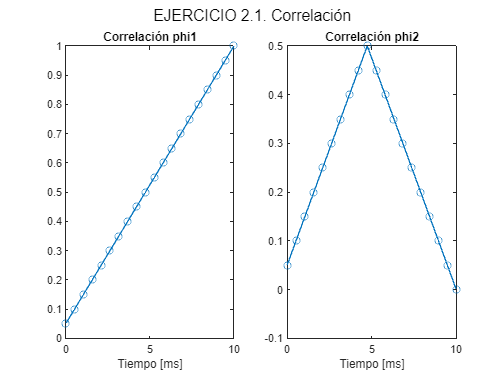

r = s1;
[y1,y2] = correlator(r,phi1,phi2,Ts);

figure;
sgtitle("EJERCICIO 2.1. Correlación")
subplot(1,2,1);
plot(t,y1/sqrt(T),'o-');
xlim([0,T*1e3]);
title("Correlación phi1");
xlabel("Tiempo [ms]");

subplot(1,2,2);
plot(t,y2/sqrt(T),'o-');
xlim([0,T*1e3]);
title("Correlación phi2");
xlabel("Tiempo [ms]");

Estas gráficas muestran el resultado de la suma acumulativa del vector resultado de la correlación, siendo el valor más importante el último graficado. Aquella salida que coincide con el símbolo de entrada obtiene un valor la unidad, mientras que otras salidas deberán presentar el valor nulo. El instante ideal de muestreo será aquel que cumpla $\textrm{kTs}=T$ es decir al final del periodo de símbolo. En este caso será en la muestra número 20.

En presencia de ruido se observa que el coeficiente nulo toma un valor distinto de cero y las gráficas presentan una mayor distorsión en amplitud debido a la adición de este ruido

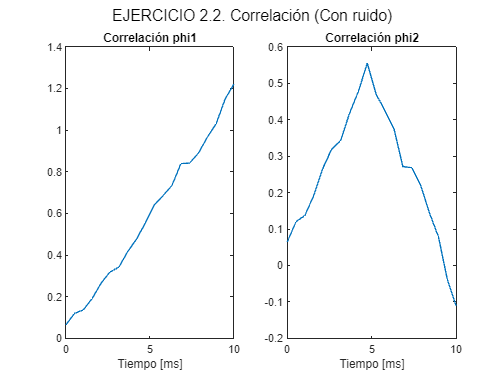

% Se introduce ruido en la señal s1(t)
pow = -5;
rn = add_awgn(s1,pow);

% Se realiza la correlación al igual que en el caso anterior
[an1,an2] = correlator(rn,phi1,phi2,Ts);
figure;
sgtitle("EJERCICIO 2.2. Correlación (Con ruido)")
subplot(1,2,1);
plot(t,an1/sqrt(T));
xlim([0,T*1e3]);
title("Correlación phi1");
xlabel("Tiempo [ms]");

subplot(1,2,2);
plot(t,an2/sqrt(T));
xlim([0,T*1e3]);
title("Correlación phi2");
xlabel("Tiempo [ms]");

Otra posible forma de realizar esta operación es a partir de la correlación cruzada. Esta operación es una medida de similitud de dos señales obtenida a partir del desplazamiento y convolución de una sobre otra. Existen diferentes implementaciones de esta operación, una muy utilizada es a partir de la transformada de Fourier o a partir de la convolución circular. Aunque son equivalentes, en este caso se muestra empleando la convolución circular.

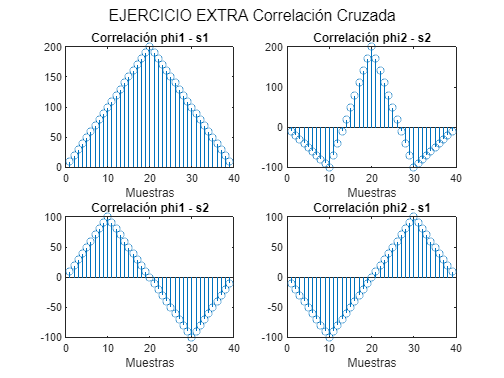

% Convolución circular
c1 = cconv(s1,conj(fliplr(phi1)));
c2 = cconv(s2,conj(fliplr(phi2)));
c3 = cconv(s2,conj(fliplr(phi1)));
c4 = cconv(s1,conj(fliplr(phi2)));

figure;
sgtitle("EJERCICIO EXTRA Correlación Cruzada")
subplot(2,2,1);
stem(c1)
title("Correlación phi1 - s1");
xlabel("Muestras");
subplot(2,2,2);
stem(c2)
title("Correlación phi2 - s2");
xlabel("Muestras");
subplot(2,2,3);
stem(c3)
title("Correlación phi1 - s2");
xlabel("Muestras");
subplot(2,2,4);
stem(c4)
title("Correlación phi2 - s1");
xlabel("Muestras");

Una idea para utilizar este método de correlación es tomar el valor máximo de la misma, lo que en el integrador seria el equivalente a resolver la integral en el periodo de símbolo para obtener un único valor. Si se introduce ruido se observa lo siguiente

% Se añade un ruido de potencia relativamente alta (1dBW)
pow = 1;
rn = add_awgn(s1,pow);
[an1,an2] = correlator(rn,phi1,phi2,Ts);
an1 = sum(an1);
an2 = sum(an2);
bn1 = max(cconv(rn,conj(fliplr(phi1))));
bn2 = max(cconv(rn,conj(fliplr(phi2))));

%Comparación Integración vs Correlación Cruzada CON RUIDO (tabla)
Simbolo = ['resultado phi1';'resultado phi2'];
Integracion = [sum(an1)/sqrt(T);sum(an2)/sqrt(T)];
Cruzada = [sum(bn1);sum(bn2)];
table(Simbolo,Integracion,Cruzada)

ans = 2×3 table
       Simbolo        Integracion    Cruzada
    ______________    ___________    _______

    resultado phi1      8.8569       181.95 
    resultado phi2      3.2224       99.488 


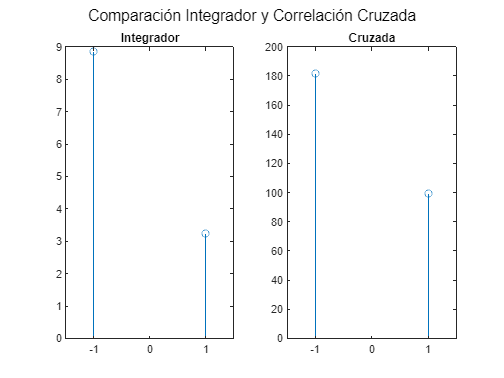

%Comparación Integración vs Correlación Cruzada CON RUIDO (gráfico)
figure;
sgtitle("Comparación Integrador y Correlación Cruzada")
subplot(1,2,1);
stem([-1,1],abs(Integracion));
xlim([-1.5,1.5]);
title("Integrador")
subplot(1,2,2);
stem([-1,1],abs(Cruzada));
xlim([-1.5,1.5]);
title("Cruzada")

En general, el valor de la correlación cruzada suele ser mayor, pero lo importante es el valor de la diferencia de ambos métodos, donde se ve el potencial de la correlación cruzada, ya que una mayor diferencia entre coeficientes reducirá las detecciones erróneas. Como conclusión, ambos métodos podrían utilizarse en la demodulación. Sin embargo, cabe destacar que las bases utilizadas no son ideales para la operación de correlación cruzada (esto se puede ver en los subproductos de correlación obtenidos, los cuales deberían ser cuanto más reducidos en amplitud mejor), más adelante se ofrecerá un ejemplo empleando bases distintas.

Ahora se muestra el funcionamiento del filtro adaptado en la demodulación. El instante ideal de muestreo para enviar el coeficiente resultante al receptor en este caso sería $\textrm{nTs}=T$ que coincide justo con la última muestra, en este caso la muestra número 20. En este momento se muestreará un valor de la unidad en el caso de las salida correspondiente al símbolo $\textrm{s1}\left(t\right)$ y un valor cercano al nulo en el caso de la salida relacionada con el símbolo $\textrm{s2}\left(t\right)$.

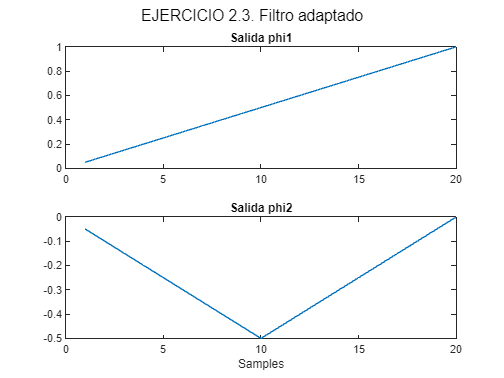

r = s1;
[c1,c2] = matchedfilter(r, s1, s2, Ts);

figure;
sgtitle("EJERCICIO 2.3. Filtro adaptado")
subplot(2,1,1);
plot(c1/T);
title("Salida phi1")
subplot(2,1,2);
plot(c2/T);
title("Salida phi2")
xlabel("Samples")

Al añadir ruido a la señal se observa lo siguiente. Parecida a la demodulación a partir de correlación, se obtiene rizado en amplitud debido al ruido añadido, lo que perjudica a la estimación final.

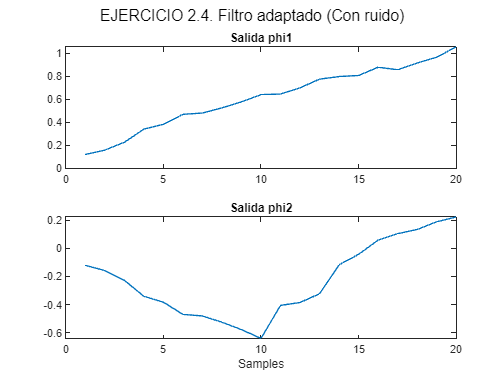

% Se añade ruido a la señal
r = s1;
pow = -5;
rn = add_awgn(r,pow);
[cn1,cn2] = matchedfilter(rn, s1, s2, Ts);

figure;
sgtitle("EJERCICIO 2.4. Filtro adaptado (Con ruido)")
subplot(2,1,1);
plot(cn1/T);
title("Salida phi1")
subplot(2,1,2);
plot(cn2/T);
title("Salida phi2")
xlabel("Samples")

A partir de los demoduladores anteriores, se han diseñado nuevos demoduladores que permiten demodular una señal contaminada por ruido blanco. Se muestra el histograma de los valores obtenidos de cada coeficiente. Se puede observar como las "colas" de los histogramas coinciden en ciertos puntos. En este caso se dará una situación de conflicot en el detector, dándose errores a la hora de determinar de qué símbolo se trata, a medida que aumente el ruido introducido, mayor coincidencia es esperada y por tanto mayor error en el detector. Esto se puede observar en los histogramas mostrados a continuación

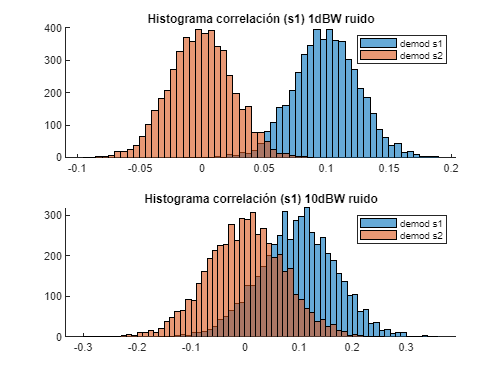

% Número de símbolos
Nsymb = 5000;

% Creación de señal (se repite el símbolo s1)
x_mod = repmat(s1,Nsymb,1);

% Se añade ruido a la señal
pow = 1;
x_mod = add_awgn(x_mod,pow);

% Se realiza la demodulación
[d1,d2] = demodulatorcorrelator(x_mod, Nsymb, phi1, phi2, Ts);

x_mod = repmat(s1,Nsymb,1);

% Se añade más ruido a la señal (aumentar coincidencia de colas)
pow = 10;
x_mod = add_awgn(x_mod,pow);

% Se realiza la demodulación
[dn1,dn2] = demodulatorcorrelator(x_mod, Nsymb, phi1, phi2, Ts);

figure;
subplot(2,1,1);
hold on;
histogram(d1);
histogram(d2);
title("Histograma correlación (s1) 1dBW ruido");
legend("demod s1","demod s2");
subplot(2,1,2);
hold on;
histogram(dn1);
histogram(dn2);
title("Histograma correlación (s1) 10dBW ruido");
legend("demod s1","demod s2");

Este solapamiento cuanto mayor sea implica un mayor error en el detector. A continuación se muestra el resultado demodulando con una señal formada por el símbolo $\textrm{s2}\left(t\right)$. Las conclusiones son análogas a las expuestas anteriormente.

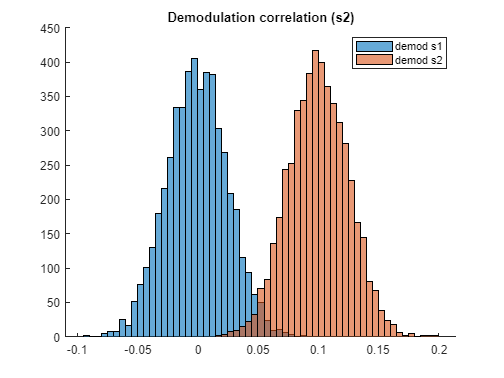

pow = 1;
x_mod = repmat(s2,Nsymb,1);
x_mod = add_awgn(x_mod,pow);
[d1,d2] = demodulatorcorrelator(x_mod, Nsymb, phi1, phi2, Ts);

figure;
hold on;
histogram(d1);
histogram(d2);
title("Demodulation correlation (s2)");
legend("demod s1","demod s2");

### EJERCICIO 3.2 DEMODULACIÓN SEÑALES DEMODULACIÓN POR FILTRO ADAPTADO

Empleando el filtro adaptado para la demodulación no se aprecian diferencias. Las conclusiones son análogas a las expuestas en la demodulación por correlación. Se incluye este apartado como prueba de que se ha realizado una función de demodulación a partir del filtro adaptado.

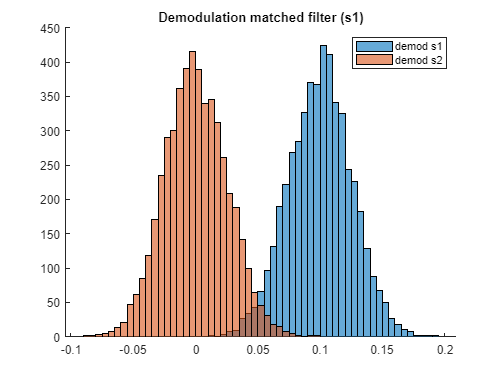

Nsymb = 5000;
x_mod = repmat(s1,Nsymb,1);
pow = 1;
x_mod = add_awgn(x_mod,pow);

[e1,e2] = demodulatormatchedfilter(x_mod, Nsymb, phi1, phi2, Ts);

figure;
hold on;
histogram(e1);
histogram(e2);
title("Demodulation matched filter (s1)");
legend("demod s1","demod s2");

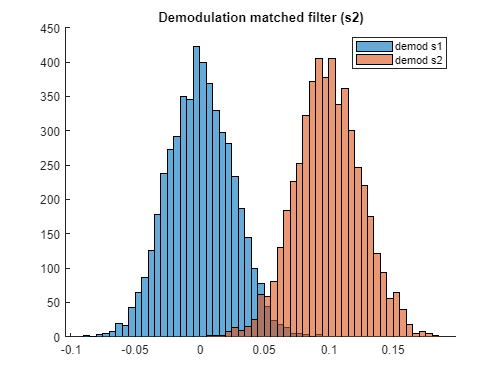

x_mod = repmat(s2,Nsymb,1);
x_mod = add_awgn(x_mod,pow);

[e1,e2] = demodulatormatchedfilter(x_mod, Nsymb, phi1, phi2, Ts);

figure;
hold on;
histogram(e1);
histogram(e2);
title("Demodulation matched filter (s2)");
legend("demod s1","demod s2");

## PARTE 2

### EJERCICIO 2.1 MODULACIÓN CON CUATRO SÍMBOLOS Y SEÑAL ALEATORIA

En esta primer ejercicio en primer lugar se crean los símbolos a utilizar a lo largo de toda la segunda parte.

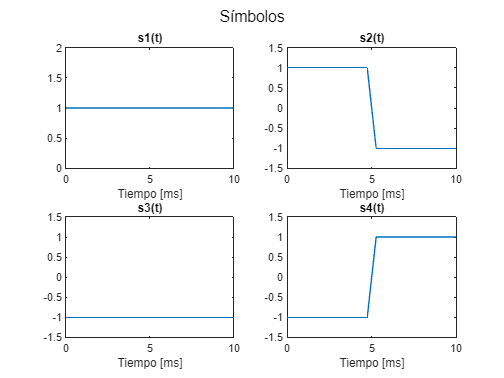

% Definición de parámetros para la generación de señales
T = 1e-2;   % Tiempo de símbolo [s/simbolo]
Ts = T/20;  % Periodo de símbolo [s/muestras]
fs = 1/Ts;  % Frecuencia de símbolo [muetras/s]
N = fs*T;   % Muestras por símbolo [muestras/simbolo]
A = 1;      % Amplitud base normalizada

% Generación de símbolos
s1 = ones(1,N);
s2 = [ones(1,N/2), -1.*ones(1,N/2)];
s3 = -1.*s1;
s4 = -1.*s2;

% Normalización de bases
phi1 = (1/(A*sqrt(T)))*s1;
phi2 = (1/(A*sqrt(T)))*s2;

% Generación eje de tiempos
t = linspace(0,N*Ts*1e3,N);

% Representación de señales
figure;
sgtitle("Símbolos")
subplot(2,2,1);
plot(t,s1);
xlim([0,T*1e3]);
title("s1(t)");
xlabel("Tiempo [ms]");

subplot(2,2,2);
plot(t,s2);
ylim([-1.5,1.5]);
xlim([0,T*1e3]);
title("s2(t)");
xlabel("Tiempo [ms]");

subplot(2,2,3);
plot(t,s3);
ylim([-1.5,1.5]);
xlim([0,T*1e3]);
title("s3(t)");
xlabel("Tiempo [ms]");

subplot(2,2,4);
plot(t,s4);
ylim([-1.5,1.5]);
xlim([0,T*1e3]);
title("s4(t)");
xlabel("Tiempo [ms]");

Una vez creados, a continuación se crea el vector de bits aleatorio, que es pasado como parámetro a la función modulator (definida al final del documento).

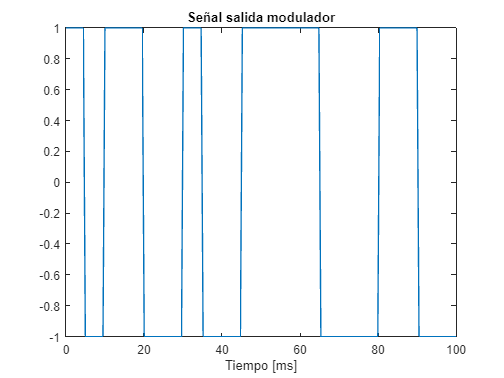

% Genración de vector de bits
Nsymb = 10;                 % Número de símbolos en la señal
M = 4;                      % Número de símbolos diferentes disponibles
n = log2(M);                % Número de bits por símbolo
Nbits = n*Nsymb;            % Número de bits total en la señal
x = round(rand(1,Nbits));   % Vector de bits aleatorio

% Modulación
S = modulator(x,Nsymb,N,s1,s2,s3,s4);

% Crear vector de símbolos para representación
v=[];
for i=1:size(S,1)
    v=[v S(i,:)];
end

% Eje de tiempos en milisegundos para representación
t = linspace(0,Nsymb*T*1e3,length(v));

figure;
plot(t,v);
title("Señal salida modulador");
xlabel("Tiempo [ms]");

### EJERCICIO 3.1: DEMODULACIÓN

Una vez obtenida la señal modulada se procede a realizar la demodulación. a la salida del demodulador implementado se observan los coeficientes normalizados. Estos valores son de esperar y coinciden con los símbolos creados anteriormente de la siguiente forma:

- En la señal y1 el valor 1 indica el símbolo $\textrm{s1}\left(t\right)$ y el valor -1 indica el símbolo $\textrm{s3}\left(t\right)$

- En la señal y2 el valor 1 indica el símbolo $\textrm{s2}\left(t\right)$ y el valor -1 indica el símbolo $\textrm{s4}\left(t\right)$

La asignación de estos coeficientes depende de las bases empleadas. Como $\phi_1$ y $\phi_2$ (las bases utilziadas) han sido creadas a partir de $\textrm{s1}\left(t\right)$ y $\textrm{s2}\left(t\right)$ respectivamente, cuando coinciden uno con otro se obtiene el valor la unidad. Si las bases se hubiesen creado a partir de $\textrm{s3}\left(t\right)$ y $\textrm{s4}\left(t\right)$ se invertirían las asignaciones ya que $\textrm{s1}\left(t\right)$ = $-\textrm{s3}\left(t\right)$ y $\textrm{s2}\left(t\right)$ = $-\textrm{s4}\left(t\right)$.

% Demodulador
[y1,y2] = demodulatorcorrelator(S, Nsymb, phi1, phi2, Ts);
y1 = y1/sqrt(T)

y1 =      0
     1
    -1
     0
     0
     1
     0
    -1
     1
    -1


y2 = y2/sqrt(T)

y2 =      1
     0
     0
     1
    -1
     0
     1
     0
     0
     0


A continuación se muestra la función detector implementada en funcionamiento. La expresión $D~=S$ devolverá el valor de la unidad en aquella posición donde se encuentre una diferencia entre las dos matrices, en el caso de no encontrarse se devolverá un nulo.

% Detector
threshold = 0;
D = detector(y1,y2,threshold,Nsymb,N,s1,s2,s3,s4);
D~=S

ans = 10×20 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Como se puede observar, al no introducir ruido en la señal la detección es ideal, ya que esta ha acertado todos los símbolos enviados sin cometer errores. Sin embargo, si se introduce ruido en la señal se observa lo siguiente.

% Introducción de ruido en la señal modulada
pow = -1e3;     % Potencia del ruido expresada en dbW
Sn = add_awgn(S,2);

% Demodulador
[y1n,y2n] = demodulatorcorrelator(Sn, Nsymb, phi1, phi2, Ts);
y1n = y1n/sqrt(T);
y2n = y2n/sqrt(T);

% Detector
threshold = 0;
D = detector(y1n,y2n,threshold,Nsymb,N,s1,s2,s3,s4);
D~=S

ans = 10×20 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0
   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0


En este caso se puede observar como el detector falla en reconocer ciertos símbolos. A mayor ruido introducido, mayor fallo en la detección. Esto guarda relación con lo explicado en la parte primera de este documento.

A continuación se ofrece una gráfica mostrando la tasa de error de bit o BER (Bit Error Rate) a partir de un SNR variable y una señal con 10000 símbolos.

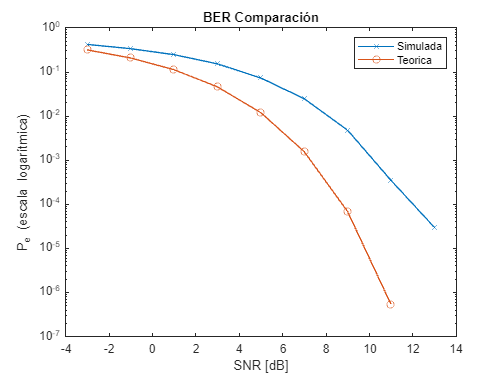

M=4; % 4-symbol alphabet
EsN0_dB = 0:2:20; % Vector to simulate SNR
esn0_lin=10.^(EsN0_dB/10); % in linear units
ebn0_lin=esn0_lin/log2(M); % bit energy / noise linear units
EbN0_dB=10*log10(ebn0_lin); % bit energy / noise dBs
Nsymb = 10000; % Number of symbols
numErr = zeros(1,length(EsN0_dB)); % Pre-allocation
 
% Definición de parámetros para la generación de señales
T = 1e-2;   % Tiempo de símbolo [s/simbolo]
Ts = T/20;  % Periodo de símbolo [s/muestras]
fs = 1/Ts;  % Frecuencia de símbolo [muetras/s]
N = fs*T;   % Muestras por símbolo [muestras/simbolo]
A = 1;      % Amplitud base normalizada

% Generación de símbolos
s1 = ones(1,N);
s2 = [ones(1,N/2), -1.*ones(1,N/2)];
s3 = -1.*s1;
s4 = -1.*s2;

phi1 = (1/(A*sqrt(T)))*s1;
phi2 = (1/(A*sqrt(T)))*s2;

% Genración de vector de bits
Nsymb = 100000;             % Número de símbolos en la señal
M = 4;                      % Número de símbolos diferentes disponibles
n = log2(M);                % Número de bits por símbolo
Nbits = n*Nsymb;            % Número de bits total en la señal
threshold = 0.5;

% Compute Pe for every SNR value
% ---- Tx ----
% Generate Nsymb random equiprobable symbols
s = round(rand(1,Nbits));   % Vector de bits aleatorio;
% Modulate symbolss
s_t = modulator(s,Nsymb,N,s1,s2,s3,s4);

for iter_EsN0= 1:length(EsN0_dB)
    
    % ---- Channel ----
    % Compute symbols' power
    SNR_awgn_dB=EsN0_dB(iter_EsN0)+10*log10(2*Ts/T); % Compute corresponding SNR for the signal
    r_t = awgn(s_t,SNR_awgn_dB,'measured'); % Add noise
 
    % ---- Rx ----
    [y1,y2] = demodulatorcorrelator(r_t,Nsymb,phi1,phi2,Ts);
    y1 = y1/sqrt(T);
    y2 = y2/sqrt(T);

    s_det = detector(y1,y2,threshold,Nsymb,N,s1,s2,s3,s4);
    
    % Compute number of wrong symbols comparing s_det with s
    numErr(iter_EsN0) = sum(max(s_det~=s_t,[],2));
    
end
% Compute simulated Symbol Error Probability
Pe = numErr/Nsymb;

% Compute theoretical performance
PeTheo = 2*qfunc(sqrt(2*log2(M)*ebn0_lin)*sin(pi/M));
PeTheo(find(PeTheo<1e-7))=NaN;

% Plot performance
figure;
grid on;
semilogy(EbN0_dB,Pe,'x-');
hold on;
semilogy(EbN0_dB,PeTheo,'o-');
title("BER Comparación");
xlabel('SNR [dB]');
ylabel('P_e (escala logarítmica)');
legend('Simulada','Teorica');

Como era de esperar, el BER simulado resulta ser peor que el teórico, ya que a mismo valor de SNR se obtiene un valor mayor de probabilidad de error en la simulación que en la teoría.

En presencia de ruido de allta frecuencia, la correlación cruzada con unas bases apropiadas es capaz de distinguir correctamente los coeficientes. En la anterior parte de introducción a la correlación cruzada, al graficar su operación se pueden observar múltiples subproductos de esta correlación que pueden afectar a la estimación final. Esto es debido a que las bases utilizadas no resultabán óptimas para esta operación.

Una posible base a utilizar es la señal CHIRP o coseno desplazado en frecuencia. Es muy utilizada en RADAR por su estrecho producto de correlación, eliminando posibles lóbulos secundarios que pudiesen afectar a la fase de detección. A continuación se muestra el aspecto de esta señal.

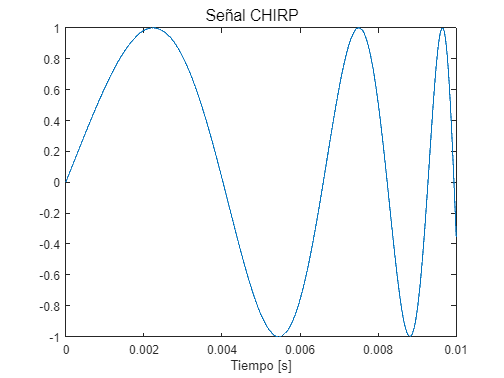

clear all;

% Generación de señal CHIRP para visualización.
T = 1e-2;
fs = 1e6;
fmax = 1e3;
fmin = 100;
initial_phase = 0;
t = linspace(0,T,T*fs);
x = sin(initial_phase+2*pi*((-fmin*fmax*T)/(fmax-fmin))*log(1-((fmax-fmin)/(fmax*T))*t));

figure;
sgtitle("Señal CHIRP");
plot(t,x);
xlabel("Tiempo [s]");

A partir de esta señal CHIRP se generan dos bases. En primer lugar se generan una base formada por dos vectores $\phi_1 \left(t\right)$ y $\phi_2 \left(t\right)$. Siendo una la versión invertida de la otra. Esto permitirá que las correlaciones alcanzen su máximo valor solamente en casos de coincidencia EXACTA. Anteriormente se implementó la operación de correlación cruzada a partir de una convolucion circular, en este caso se aplicará la fft.

Idealmente, se deberia añadir un padding para lograr una longitud de señal entrante potencia de dos, sin embargo como el objetivo de esta demostración es solamente mostrar el potencial de la correlación cruzada se omitirá este paso, al igual que aplicar un filtrado previo a la señal para evitar cambios de frecuencia bruscos.

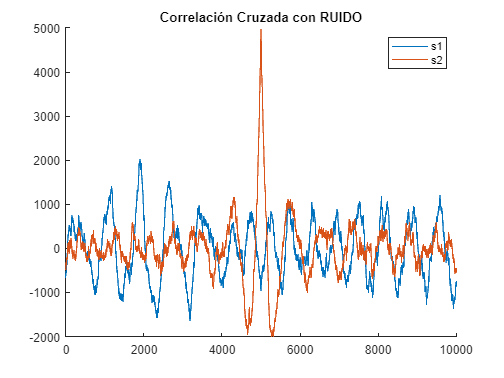

% Generación de señales
T = 1e-2;
fs = 1e6;               % Mayor frecuencia de muestreo para permitir mejor visualización de las gráficas
Ts = T/20;
fmax = 1e6;
fmin = 1e3;
initial_phase = 0;
t = linspace(0,T,T*fs);

s1 = sin(initial_phase+2*pi*((-fmin*fmax*T)/(fmax-fmin))*log(1-((fmax-fmin)/(fmax*T))*t));
s2 = fliplr(s1);

% Normalización de bases
phi1 = s1/max(s1);
phi2 = s2/max(s2);

% Se introduce ruido de ALTA potencia (en dBW)
pow = 10;   
r = add_awgn(s2,pow);
y = ifftshift(ifft(fft(r).*conj(fft(phi1))));
z = ifftshift(ifft(fft(r).*conj(fft(phi2))));

figure;
hold on;
plot(y);
plot(z);
title("Correlación Cruzada con RUIDO");
legend('s1','s2');

El muestreo del valor del coeficiente debe realizarse en el punto medio de la señal de salida, es decir se debe muestrear el coeficiente en $\frac{T}{2}$. En este caso este tiempo corresponde con la muestra número 5001.

Se observa que la señal CHIRP puede llegar a ser útil en casos de alta potencia de ruido, sin embargo al ser una señal que varía mucho en frecuencia la transmisión de los símbolos consumirá un mayor ancho de banda. Comparando entre las diferentes salidas (tantas como símbolos posibles) y determinando cuál de estas posee el coeficiente con mayor valor es posible determinar qué símbolo fue transmitido.

% Generación de vector de bits
Nsymb = 10;                 % Número de símbolos en la señal
M = 4;                      % Número de símbolos diferentes disponibles
n = log2(M);                % Número de bits por símbolo
Nbits = n*Nsymb;            % Número de bits total en la señal
x = round(rand(1,Nbits));   % Vector de bits aleatorio

S = zeros(Nsymb, length(s1));   % Prealocar matriz para símbolos (mayor rapidez)

for i = 1:Nsymb
    if x(i) == 0
        S(i,:) = s1;
    else
        S(i,:) = s2;
    end
end

% Introducción de ruido en la señal modulada
pow = 10;     % Potencia del ruido expresada en dbW
Sn = add_awgn(S,2);

% Demodulador
y1 = zeros(Nsymb,1);
y2 = zeros(Nsymb,1);

for i=1:Nsymb
    aux_y1 = ifftshift(ifft(fft(Sn(i,:)).*conj(fft(phi1))));
    aux_y2 = ifftshift(ifft(fft(Sn(i,:)).*conj(fft(phi2))));
    y1(i) = aux_y1((length(phi1)/2)+1);
    y2(i) = aux_y2((length(phi1)/2)+1);
end

% Detector
D = zeros(Nsymb,length(s1));
for i=1:length(y1)
    if y1(i) > y2(i)
        D(i,:) = s1;
    else
        D(i,:) = s2;
    end
end
D~=S

ans = 10×10000 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

Como se puede observar, incluso con alta potencia de ruido (10 dBW en este ejemplo) este método ofrece muy buenos resultados, logrando tasas de error nula con mucha potencia de ruido. De nuevo destacar que este método, auqneu extremadamente resiliente frente al ruido, requeriría un amyor ancho de banda en el envío de los símbolos debido a la naturaleza senoidal de frecuencia variable de las bases y símbolos utilizados.

### FUNCIONES UTILIZADAS

function [y1,y2] = correlator(r, phi1, phi2, Ts)
    y1 = Ts*(r.*phi1);
    y2 = Ts*(r.*phi2);
    y1 = cumsum(y1);
    y2 = cumsum(y2);
end

function y = add_awgn(s_rx,pow)
    [row,col] = size(s_rx);
    y = s_rx + wgn(row,col,pow);
end

function [y1,y2] = matchedfilter(r, phi1, phi2, Ts)
    m1 = fliplr(phi1);
    m2 = fliplr(phi2);
    y1 = Ts*filter(m1,1,r);
    y2 = Ts*filter(m2,1,r);
end

function S = modulator(x,Nsymb,N,s1,s2,s3,s4)
    i = 1:2:length(x);          % Vector de números impares (tomar el primer bit de cada símbolo)
    p = 2:2:length(x);          % Vector de símbolos pares (tomar el segundo bit de cada símbolo)
    S = zeros(Nsymb, N);        % Prealocar matriz para símbolos (mayor rapidez)
    
    for z = 1:Nsymb
        if x(i(z)) == 0 && x(p(z)) == 0
            S(z,:) = s1;
        elseif x(i(z)) == 0 && x(p(z)) == 1
            S(z,:) = s2;
        elseif x(i(z)) == 1 && x(p(z)) == 0
            S(z,:) = s3;
        elseif x(i(z)) == 1 && x(p(z)) == 1
            S(z,:) = s4;
        end
    end
end

function [y1,y2] = demodulatorcorrelator(x, Nsymb, phi1, phi2, Ts)
    y1 = zeros(Nsymb,1);
    y2 = zeros(Nsymb,1);
    for i=1:Nsymb
        y1(i) = Ts*sum(x(i,:).*phi1);
        y2(i) = Ts*sum(x(i,:).*phi2);
    end
end

function D = detector(y1,y2,threshold,Nsymb,N,s1,s2,s3,s4)
    D = zeros(Nsymb,N);
    for i=1:length(y1)
        if y1(i) > threshold
            D(i,:) = s1;
        end
        if y1(i) < -1*threshold
            D(i,:) = s3;
        end
    end
    
    for i=1:length(y2)
        if y2(i) > threshold
            D(i,:) = s2;
        end
        if y2(i) < -1*threshold
            D(i,:) = s4;
        end
    end
end

function [y1,y2] = demodulatormatchedfilter(x, Nsymb, phi1, phi2, Ts)
    y1 = zeros(Nsymb,1);
    y2 = zeros(Nsymb,1);
    m1 = fliplr(phi1);
    m2 = fliplr(phi2);

    for i=1:Nsymb
        r1 = Ts*filter(m1,1,x(i,:));
        y1(i) = r1(end);
        r2 = Ts*filter(m2,1,x(i,:));
        y2(i) = r2(end);
    end
end